# 1.2.05. Анализ данных

**Лекция**

## Нахождение пропущенных данных

Для поиска отсутствующих данных (NaN) используется функция `isnan`, а для поиска бесконечных величин (`Inf`) используется функция `isfinite`:

Пример:

V1 = randi([-15,15],1,7);
V1([2 4])=NaN;      
V1(end) = V1(end)/0;   % результат деления на ноль - бесконечность
V1

V1 =     11   NaN    -2   NaN     1    15  -Inf


[   isnan(V1);
 isfinite(V1)]

ans = 2×7 logical array
   0   1   0   1   0   0   0
   1   0   1   0   1   1   0


Иногда требуется проверка на отсутствие данных в векторе вообще, или проверка на наличие хотя бы одного отсутствующего элемента. Для первого случая используется команда `all`, а для второго - `any`: 

V2 = NaN(1,5)     % Вектор-столбец из отсутствующих данных

V2 =    NaN   NaN   NaN   NaN   NaN


[any(isnan(V1)), all(isnan(V1));
 any(isnan(V2)), all(isnan(V2))]

ans = 2×2 logical array
   1   0
   1   1


Результатом выполнения команд `isnan` и `isfinite` по отношению к матрицам выдаст, соответственно, логические матрицы. С помощью команд `any` и `all` можно определить наличие отсутствующих данных и отсутствие данных вообще, анализируя по строкам или столбцам:

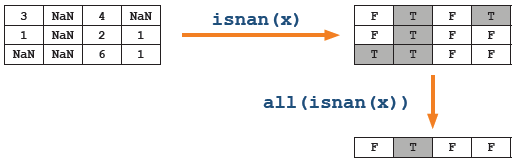

B = randi([-15,15],4,5);
B([3 1],1) = NaN; 
B(:,3) = NaN

B =    NaN     0   NaN   -10   -13
     0     7   NaN    -1   -15
   NaN     1   NaN     4   -13
   -15    15   NaN   -12    -3


isnan(B)

ans = 4×5 logical array
   1   0   1   0   0
   0   0   1   0   0
   1   0   1   0   0
   0   0   1   0   0


По умолчанию анализ ведётся по столбцам (`Dimention = 1`). Для анализа по строкам, функция `all` (или `any`) должна быть вызвана с параметром (`Dimention = 2`):

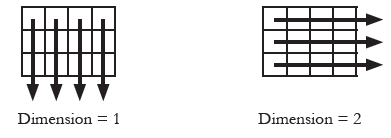

Пример:

any(isnan(B),1)     % Параметр Dimention = 1, анализ по столбцам

ans = 1×5 logical array
   1   0   1   0   0


any(isnan(B),2)     % Параметр Dimention = 2, анализ по строкам

ans = 4×1 logical array
   1
   1
   1
   1


Для поиска отсутствующих элементов таблиц используется функция `ismissing`, а именно:

    **●  **ищет `NaN` для числовых переменных

    **●  **ищет `NaT` для временных переменных

    **●  **ищет пустые текстовые переменные

     и т д.

## Работа с пропущенными данными

Существует 3 основных подхода к работе с пропущенными данными: игнорировать, удалять или присваивать им значения:

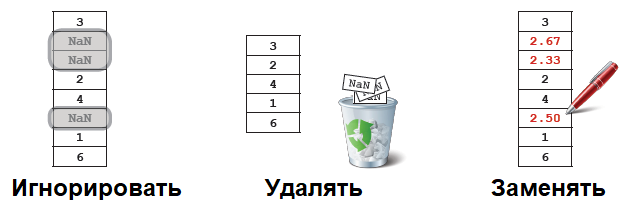

Удалять пропущенные данные можно с помощью команды `rmmissing`: 

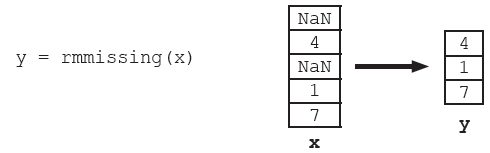

V3 = randi([1 8], 1,8);
V3([2 3 6]) = NaN

V3 =      4   NaN   NaN     7     3   NaN     6     2


rmmissing(V3)

ans =      4     7     3     6     2


В случае применения функции rmissing к матрицам удаляются все столбцы и строки, содержащие отсутствующие данные:

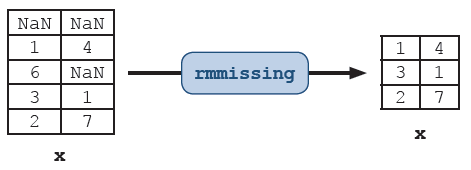

C = randi([-15,15],4,5);
C(2,2) = NaN; 
C(2,3) = NaN; 
C(4,3) = NaN'

C =    -15    -6    -9     2    -3
     3   NaN   NaN   -11    11
     9   -10    -3    -7     3
     6     1   NaN   -13    -4


rmmissing(C)

ans =    -15    -6    -9     2    -3
     9   -10    -3    -7     3


Данные можно заменить с помощью функции `fillmissing`, указав ей метод, с помощью которого будет производиться замена. Методы представлены в таблице: 

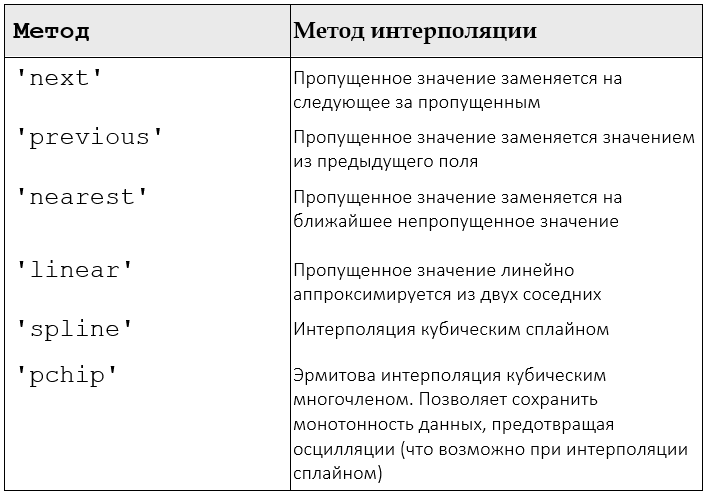

V3

V3 =      4   NaN   NaN     7     3   NaN     6     2


 fillmissing(V3,'next') 

ans =      4     7     7     7     3     6     6     2


 fillmissing(V3,'linear')

ans =     4.0000    5.0000    6.0000    7.0000    3.0000    4.5000    6.0000    2.0000


## Работа с данными

В MATLAB считает корреляцию между двумя векторами по формулам: 

где $\sigma_A$ и $\sigma_B$ - стандартные отклонения для векторов $A$ и $B$. Матрица корреляции для двух векторов имеет вид:

Для нахождения матрицы корреляций между векторами используется функция `corrcoeff`. Пример нахождения матрицы корреляций для 3-х векторов:

D1 = randn(100,1);
D2 = randi([-20,20],100,1);
D3 = 1 + rand(100,1);
corrcoef([D1,D2,D3])   

ans =     1.0000    0.1037   -0.1656
    0.1037    1.0000    0.0350
   -0.1656    0.0350    1.0000


В MATLAB также возможно выполнять сглаживание методом скользящего среднего с помощью функции `movnean`:

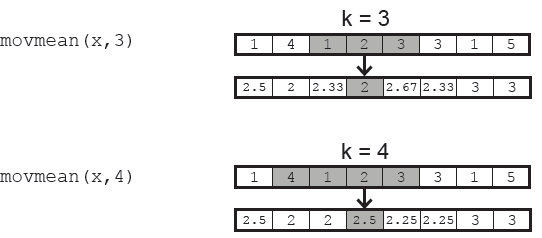

Если элементов не хватает для вычисления, то среднее берётся по оставшимся элементам:

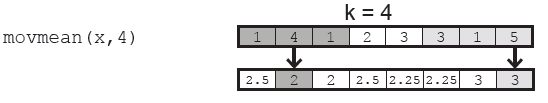

E = randi([-4 10], 1, 10)

E =     -2     0    10    10     8     9     1     9     0     7


movmean(E,3)

ans =    -1.0000    2.6667    6.6667    9.3333    9.0000    6.0000    6.3333    3.3333    5.3333    3.5000


movmean(E,8)

ans =     4.5000    5.2000    5.8333    5.1429    5.6250    5.8750    6.7500    6.2857    5.6667    5.2000
